clear; clc;

% Experimental values
gam=35*10^(-3); % Surface tension
th=2*pi/6; % Theta contact angle
mu=20*10^(-3); % Viscosity
aa=10^(-6); % Appoximate radius of the specific colloid in ink 
kBT=4*10^(-21); % Boltzmann Const times room temperature
Dt=aa^2/(6*pi); % Diffusion of the colloid (Einstein relation)
hp=10^(-6); % This is an assumed dimensional precursor height in m

y0 = .1084434390; % Raise droplet profile...
N = 120; % # sample points
A = 17; % Magnitude/Amplitude of droplet

tfinal = 10^5; % final time >> 1
t0 = 1e-6;% initial time << 1


c1 = 0.0010;  
c2 = 0.0196;

c3 = 0.0013;
c4 = 0.0108;

% tfinal = 10^5; % final time >> 1
xMax = 20; 
dx = 2*xMax/(N-1); % Stepsize
X = -xMax:dx:xMax; % Linespace/Mesh
k = 1/(2*xMax/N); %omega
% Possition / Shift
x0 = 7.5;
x1 = 15;
x = 10;
aa=-5;
bb=5;
cc=.5;

**Target Shape **`h_target`

a=round(aa/dx+N/2);
b=round(bb/dx+N/2);
c=cc*ones(size(X));

h_region = ones(size(X));
h_region(1:a) = c(1:a) + cc.*tanh((X(1:a)-aa));
h_region(a+1:(a+b)/2) = c(a+1:(a+b)/2) + (1+cc).*tanh((X(a+1:(a+b)/2)-aa)./(2));
h_region((a+b)/2+1:b) = c((a+b)/2+1:b) - (1+cc).*tanh((X((a+b)/2+1:b)-bb)./(2));
h_region(b+1:end) = c(b+1:end) - cc.*tanh((X(b+1:end)-bb));

target = [a,b,h_region];

## **2) **

**Solutions**

Inside

[tSpan,D1,D2,X,H0,myObjective,conds_Sol,...
    fval,exitflag,output,history,History,h_Sol,H_Sol,OUTS]...
    = SolutionRegion(tfinal,dx,X,k,y0,N,A,c1,c2,x0,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          102.311         
     1            4          102.311         initial simplex
     2            5          102.311         reflect
     3            7          93.7209         expand
     4            8          93.7209         reflect
     5           10          87.7865         expand
     6           12          69.2591         expand
     7           13          69.2591         reflect
     8           15          40.2812         expand
     9           17          20.2825         expand
    10           19          18.5834         reflect
    11           20          18.5834         reflect
    12           22          18.5834         contract outside
    13           24          15.1817         contract inside
    14           26          15.1817         contract inside
    15           28          14.8798         contract outside
    16           30          13.1306         contract inside
    


[~,~,~,~,H0_Possition,myObjective_Possition,conds_Sol_Possition,...
    ~,~,output_Possition,history_Possition,History_Possition,h_Sol_Possition,H_Sol_Possition,OUTS_Possition]...
    = SolutionPossition(tfinal,dx,X,k,y0,N,A,c1,c2,x0,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          102.311         
     1            2          102.311         initial simplex
     2            4          95.1813         expand
     3            6          73.9395         expand
     4            8          26.6971         expand
     5           10          20.7145         reflect
     6           12          20.7145         contract inside
     7           14          20.3025         contract inside
     8           16          20.3025         contract inside
     9           19          20.3025         shrink
    10           21          20.3025         contract outside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 20.338217 seconds.



[~,~,~,~,H0_Disjoining,myObjective_Disjoining,conds_Sol_Disjoining,...
    ~,~,output_Disjoining,history_Disjoining,History_Disjoining,h_Sol_Disjoining,H_Sol_Disjoining,OUTS_Disjoining]...
    = SolutionDisjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_Possition(end),target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          20.3025         
     1            3            18.11         initial simplex
     2            5          14.2496         expand
     3            6          14.2496         reflect
     4            8          10.0277         reflect
     5            9          10.0277         reflect
     6           10          10.0277         reflect
     7           12          10.0277         contract inside
     8           14          9.76471         contract inside
     9           16          9.60033         reflect
    10           18          9.33962         contract inside
    11           20          9.33962         contract inside
    12           22          9.33962         contract inside
    13           24          9.27663         reflect
    14           26          9.27663         contract inside
    15           28          9.27663         contract inside
 
Optimization terminated:
 the current


[~,~,~,~,H_2,~,conds_Sol_2,...
    ~,~,output_2,history_2,History_2,h_Sol_2,H_Sol_2,OUTS_2]...
    = SolutionRegion(tfinal,dx,X,k,y0,N,A,c1,c2,x,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          106.722         
     1            4          106.469         initial simplex
     2            6          105.873         expand
     3            7          105.873         reflect
     4            9          104.483         expand
     5           11          102.015         expand
     6           12          102.015         reflect
     7           14           86.139         expand
     8           16           77.847         expand
     9           17           77.847         reflect
    10           19           77.847         expand
    11           20           77.847         reflect
    12           21           77.847         reflect
    13           23           77.847         expand
    14           24           77.847         reflect
    15           25           77.847         reflect
    16           30           77.847         shrink
    17           31           77.847         refl


[~,~,~,~,H_2Possition,~,conds_Sol_2Possition,...
    ~,~,output_2Possition,history_2Possition,History_2Possition,h_Sol_2Possition,H_Sol_2Possition,OUTS_2Possition]...
    = SolutionPossition(tfinal,dx,X,k,y0,N,A,c1,c2,x,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          106.722         
     1            2          106.722         initial simplex
     2            4          106.705         expand
     3            6          99.0802         expand
     4            8          34.2542         expand
     5           10          21.1867         reflect
     6           12          21.1867         contract inside
     7           14          20.3025         contract inside
     8           16             19.3         contract inside
     9           19             19.3         shrink
    10           21             19.3         contract inside
    11           23             19.3         contract inside
    12           25             19.3         contract inside
    13           27             19.3         contract inside
    14           29             19.3         reflect
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX


[~,~,~,~,H_2Disjoining,myObjective_2Disjoining,conds_Sol_2Disjoining,...
    ~,~,output_2Disjoining,history_2Disjoining,History_2Disjoining,h_Sol_2Disjoining,H_Sol_2Disjoining,OUTS_2Disjoining]...
    = SolutionDisjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_2Possition(end),target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1             19.3         
     1            3             19.3         initial simplex
     2            5          14.8776         expand
     3            6          14.8776         reflect
     4            8           11.832         reflect
     5            9           11.832         reflect
     6           11           11.832         contract outside
     7           12           11.832         reflect
     8           14           11.832         contract inside
     9           16          11.7622         reflect
    10           20          11.7622         shrink
    11           22          11.6356         contract outside
    12           24             11.6         reflect
    13           26             11.6         contract inside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTI


[~,~,~,~,H_1,~,conds_Sol_1,...
    ~,~,output_1,history_1,History_1,h_Sol_1,H_Sol_1,OUTS_1]...
    = SolutionRegion(tfinal,dx,X,k,y0,N,A,c1,c2,x1,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          106.722         
     1            4           106.46         initial simplex
     2            6           105.88         expand
     3            7           105.88         reflect
     4            9          104.684         expand
     5           11          102.749         expand
     6           13           99.649         expand
     7           15           77.847         expand
     8           17          57.6928         expand
     9           19          52.9067         expand
    10           20          52.9067         reflect
    11           21          52.9067         reflect
    12           23          52.9067         contract outside
    13           28          52.9067         shrink
    14           33          52.9067         shrink
    15           38          52.9067         shrink
    16           43          52.9067         shrink
    17           48          52.9067       


[~,~,~,~,H_1Possition,~,conds_Sol_1Possition,...
    ~,~,output_1Possition,history_1Possition,History_1Possition,h_Sol_1Possition,H_Sol_1Possition,OUTS_1Possition]...
    = SolutionPossition(tfinal,dx,X,k,y0,N,A,c1,c2,x1,target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          106.722         
     1            2          106.722         initial simplex
     2            4          106.722         reflect
     3            7          106.722         shrink
     4           10          106.722         shrink
     5           13          106.722         shrink
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 12.274620 seconds.



[~,~,~,~,H_1Disjoining,myObjective_1Disjoining,conds_Sol_1Disjoining,...
    ~,~,output_1Disjoining,history_1Disjoining,History_1Disjoining,h_Sol_1Disjoining,H_Sol_1Disjoining,OUTS_1Disjoining]...
    = SolutionDisjoining(tfinal,dx,X,k,y0,N,A,c1,c2,history_1Possition(end),target);

 
 Iteration   Func-count     min f(x)         Procedure
     0            1          106.722         
     1            3           106.46         initial simplex
     2            5          105.736         expand
     3            7          104.705         expand
     4            9          101.229         expand
     5           11           91.265         expand
     6           13           77.847         reflect
     7           14           77.847         reflect
     8           16           77.847         contract outside
 
Optimization terminated:
 the current x satisfies the termination criteria using OPTIONS.TolX of 1.000000e-01 
 and F(X) satisfies the convergence criteria using OPTIONS.TolFun of 1.000000e-01 

Elapsed time is 6.321870 seconds.


nDisjoin = size(history_Disjoining);
nDisjoin = nDisjoin(1);

nPossition = size(history_Possition);
nPossition = nPossition(1); 

history1 = ones(nDisjoin+nPossition,3);

history1(1:nPossition,2:3) = [c1 c2].*ones(size(history_Possition));
history1(nPossition+1:end,2:3) = history_Disjoining;

history1(1:nPossition,1) = history_Possition;
history1(nPossition+1:end,1) = history_Possition(end).*ones(size(History_Disjoining));

History1 = [History_Possition;History_Disjoining];


nDisjoin_1 = size(history_1Disjoining);
nDisjoin_1 = nDisjoin_1(1);

nPossition_1 = size(history_1Possition);
nPossition_1 = nPossition_1(1); 

history1_1 = ones(nDisjoin_1+nPossition_1,3);

history1_1(1:nPossition_1,2:3) = [c1 c2].*ones(size(history_1Possition));
history1_1(nPossition_1+1:end,2:3) = history_1Disjoining;

history1_1(1:nPossition_1,1) = history_1Possition;
history1_1(nPossition_1+1:end,1) = history_1Possition(end).*ones(size(History_1Disjoining));

History1_1 = [History_1Possition;History_1Disjoining];


nDisjoin_2 = size(history_2Disjoining);
nDisjoin_2 = nDisjoin_2(1);

nPossition_2 = size(history_2Possition);
nPossition_2 = nPossition_2(1); 

history1_2 = ones(nDisjoin_2+nPossition_2,3);

history1_2(1:nPossition_2,2:3) = [c1 c2].*ones(size(history_2Possition));
history1_2(nPossition_2+1:end,2:3) = history_2Disjoining;

history1_2(1:nPossition_2,1) = history_2Possition;
history1_2(nPossition_2+1:end,1) = history_2Possition(end).*ones(size(History_2Disjoining));

History1_2 = [History_2Possition;History_2Disjoining];

**Inside Figures**

Fig. 0

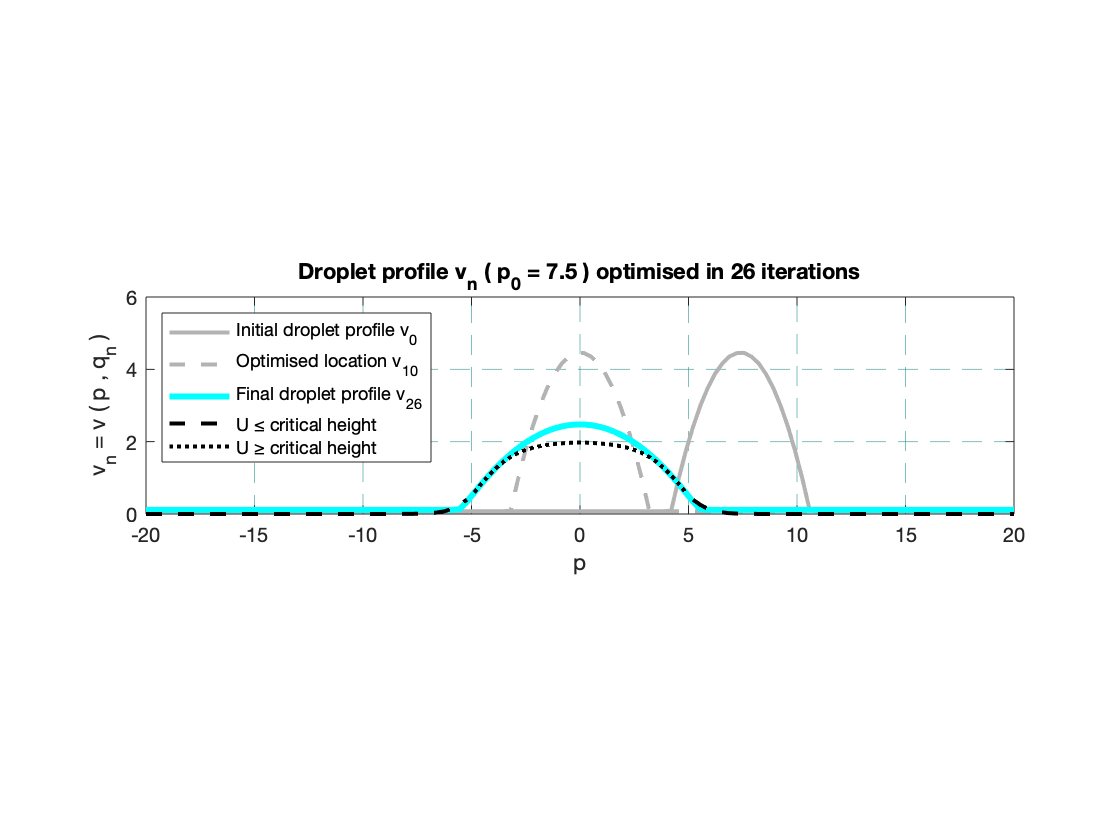

figure;
hold on
plot(X,H0_Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H0_Disjoining,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_Disjoining,'c-','linewidth',3);
plot(X(1:a),h_region(1:a),'k--','linewidth',2);
plot(X(a+1:b),h_region(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),h_region(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('v_n = v ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile v_0',...
    'Optimised location v_{10}',...
    'Final droplet profile v_{26}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile v_n ( p_0 = 7.5 ) optimised in 26 iterations');
hold off

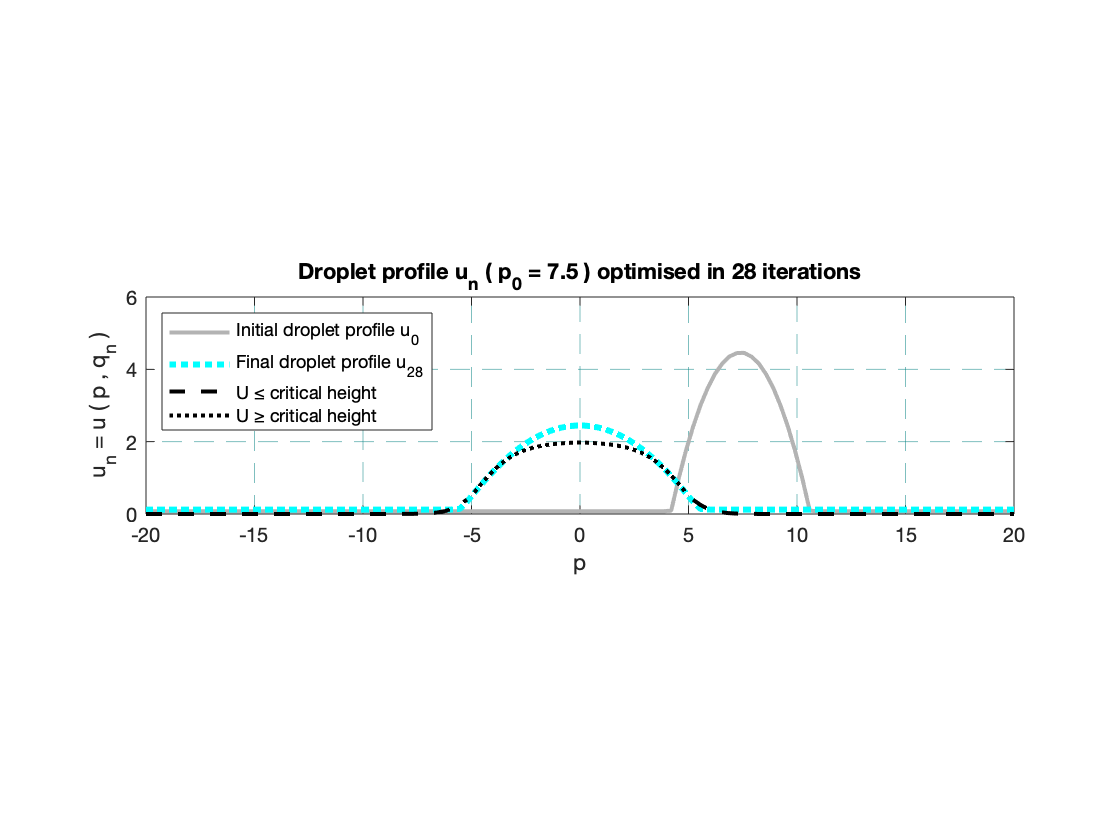


figure;
hold on
plot(X,H0_Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol,'c:','linewidth',3);
plot(X(1:a),h_region(1:a),'k--','linewidth',2);
plot(X(a+1:b),h_region(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),h_region(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{28}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile u_n ( p_0 = 7.5 ) optimised in 28 iterations');
hold off

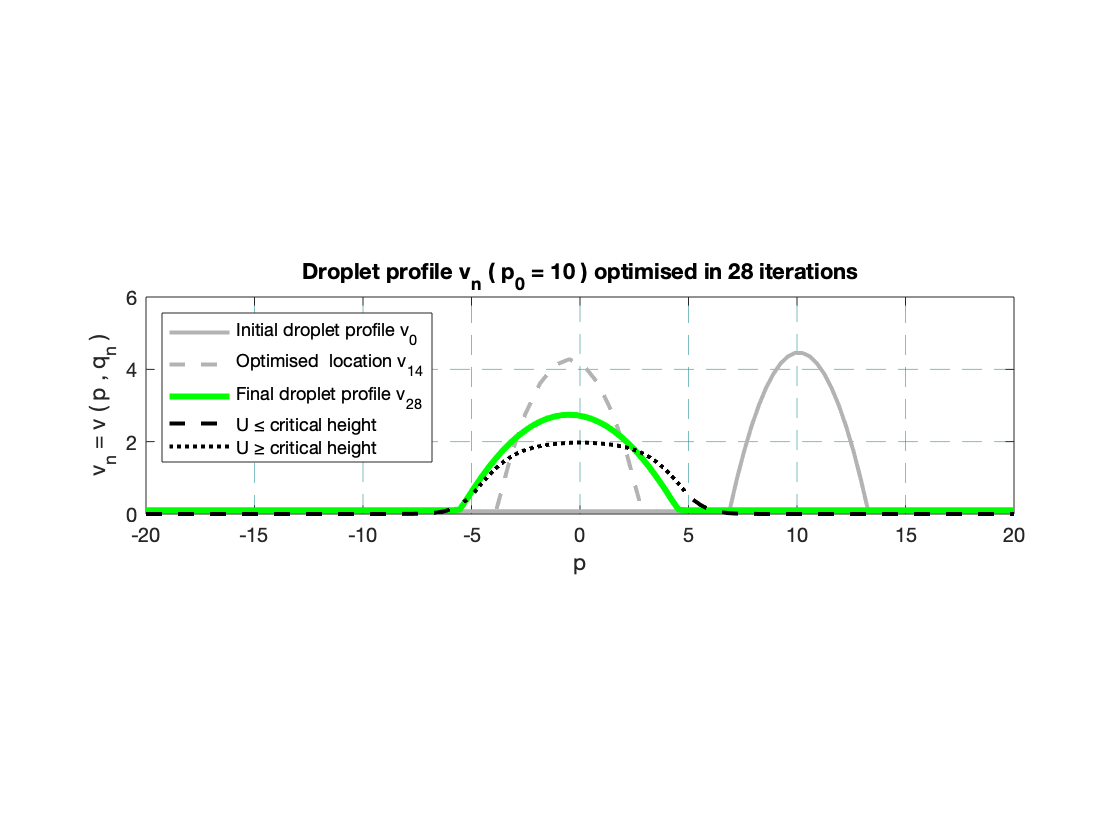



figure;
hold on
plot(X,H_2Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_2Disjoining,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_2Disjoining,'g-','linewidth',3);
plot(X(1:a),h_region(1:a),'k--','linewidth',2);
plot(X(a+1:b),h_region(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),h_region(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('v_n = v ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile v_0',...
    'Optimised  location v_{14}',...
    'Final droplet profile v_{28}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile v_n ( p_0 = 10 ) optimised in 28 iterations');
hold off

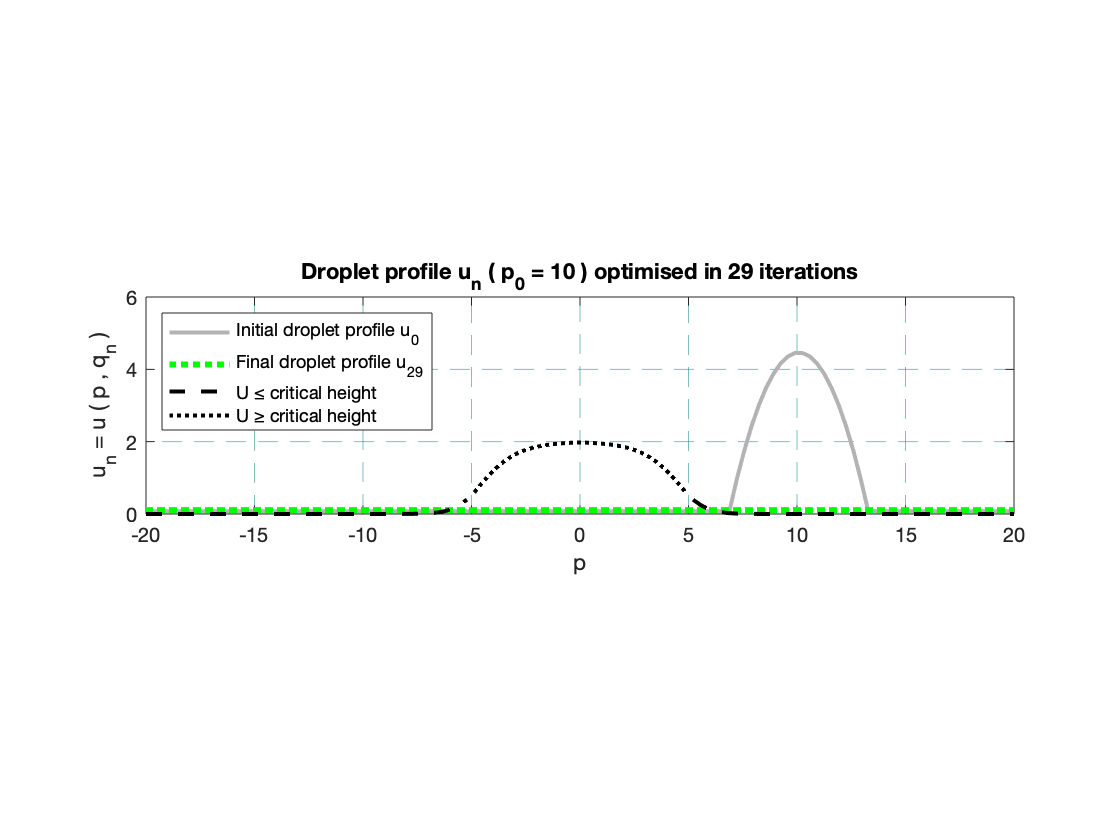


figure;
hold on
plot(X,H_2Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_2,'g:','linewidth',3);
plot(X(1:a),h_region(1:a),'k--','linewidth',2);
plot(X(a+1:b),h_region(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),h_region(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{29}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile u_n ( p_0 = 10 ) optimised in 29 iterations');
hold off

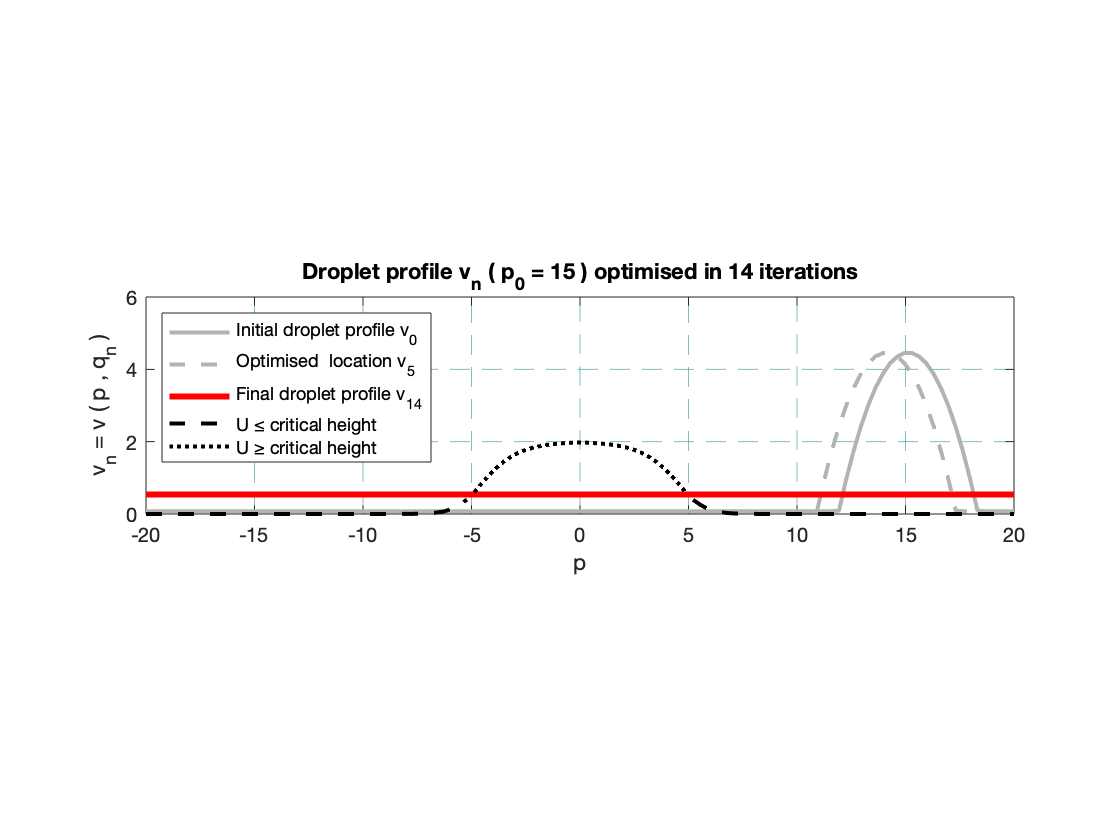



figure;
hold on
plot(X,H_1Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_1Disjoining,'--','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_1Disjoining,'r-','linewidth',3);
plot(X(1:a),h_region(1:a),'k--','linewidth',2);
plot(X(a+1:b),h_region(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),h_region(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('v_n = v ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile v_0',...
    'Optimised  location v_{5}',...
    'Final droplet profile v_{14}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile v_n ( p_0 = 15 ) optimised in 14 iterations');
hold off

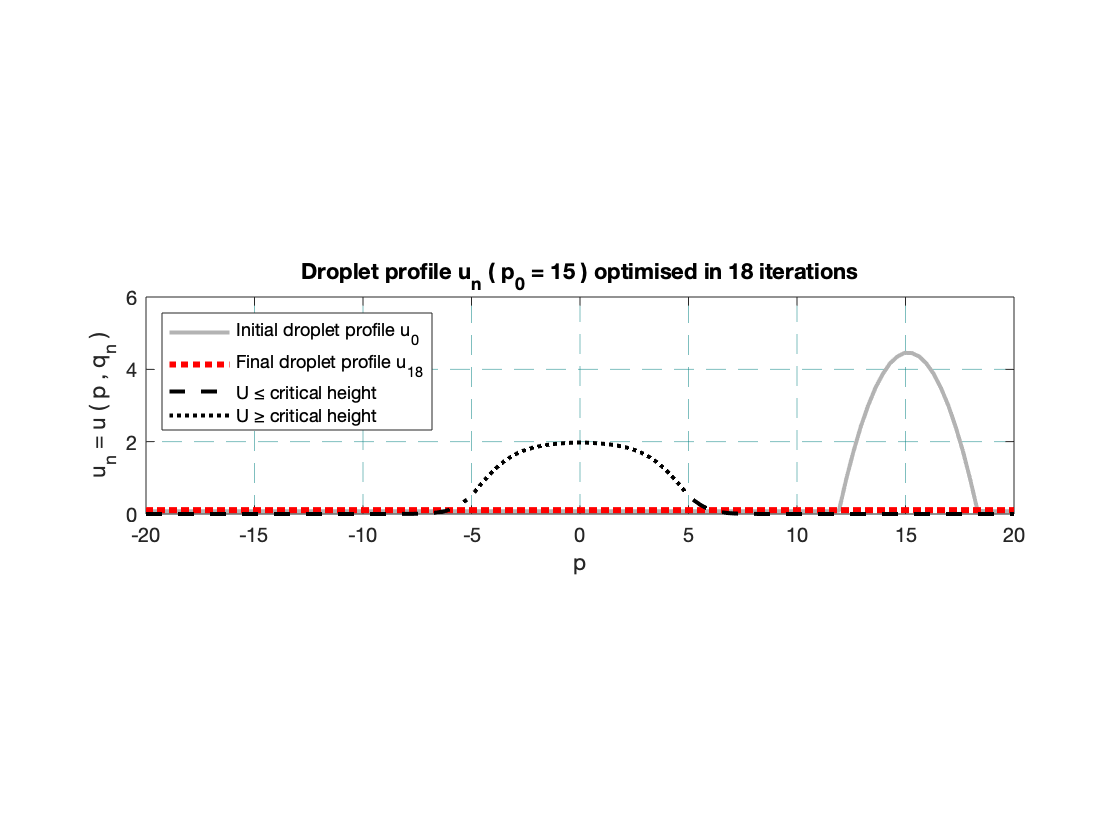


figure;
hold on
plot(X,H_1Possition,'-','Color',[0.7 0.7 0.7],'linewidth',2);
plot(X,H_Sol_1,'r:','linewidth',3);
plot(X(1:a),h_region(1:a),'k--','linewidth',2);
plot(X(a+1:b),h_region(a+1:b),'k:','linewidth',2);
plot(X(b+1:end),h_region(b+1:end),'k--','linewidth',2);
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;
legend('Initial droplet profile u_0',...
    'Final droplet profile u_{18}',...
    'U ≤ critical height',...
    'U ≥ critical height',...
    'Location','northwest');
title('Droplet profile u_n ( p_0 = 15 ) optimised in 18 iterations');
hold off

**Joint Figures**

Fig. 1

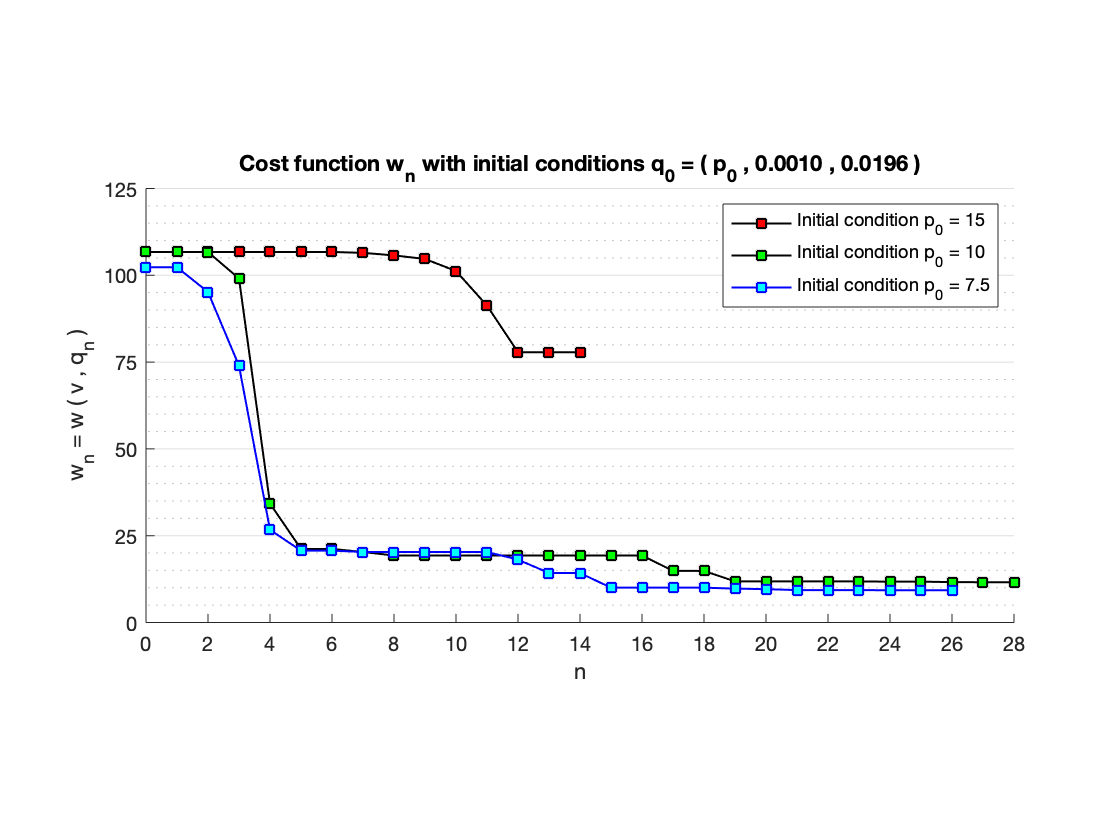

figure;
hold on
plot(0:14,History1_1,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:28,History1_2,'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:26,History1,'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('w_n = w ( v , q_n )');
xlabel('n');
legend('Initial condition p_0 = 15','Initial condition p_0 = 10','Initial condition p_0 = 7.5','Location','northeast');
title('Cost function w_n with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 28]);
ylim([0 125]);
set(gca,'xtick',-4:2:500);
set(gca,'ytick',0:25:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

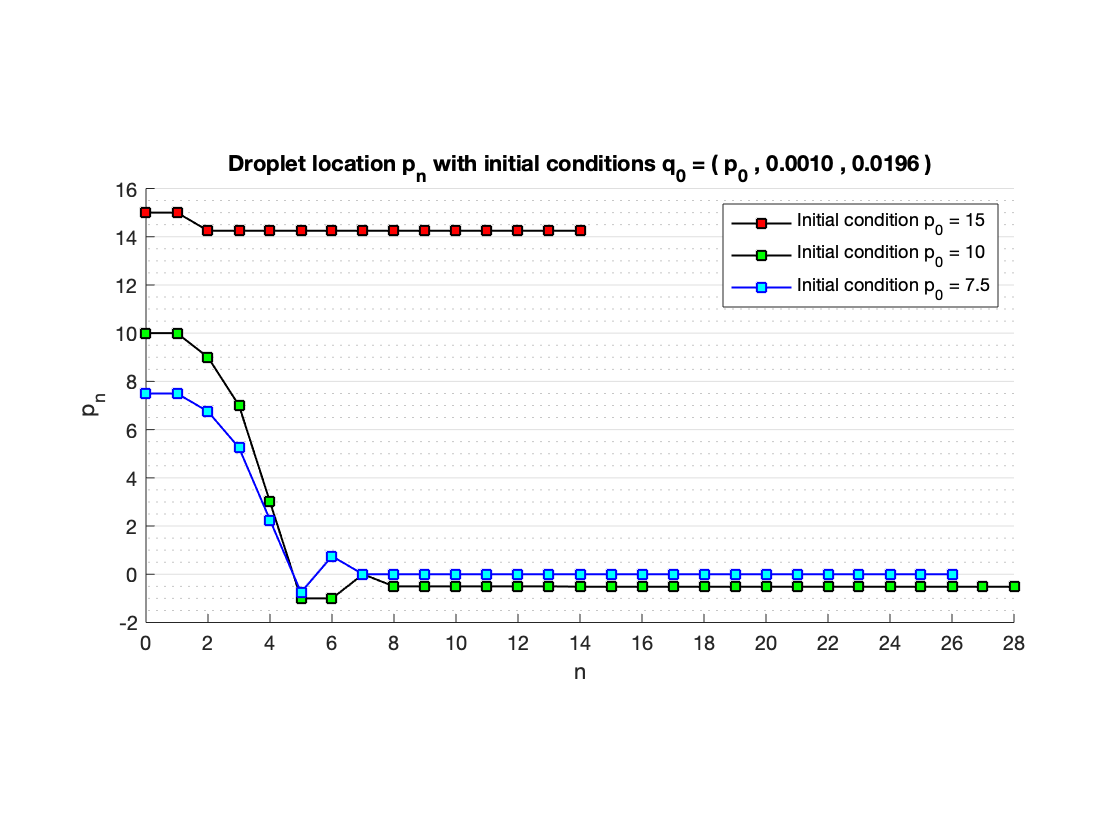


figure;
hold on
plot(0:14,history1_1(:,1),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:28,history1_2(:,1),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:26,history1(:,1),'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('p_n');
xlabel('n');
legend('Initial condition p_0 = 15','Initial condition p_0 = 10','Initial condition p_0 = 7.5','Location','northeast');
title('Droplet location p_n with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 28]);
ylim([-2 16]);
set(gca,'ytick',-4:2:500);
set(gca,'xtick',-4:2:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

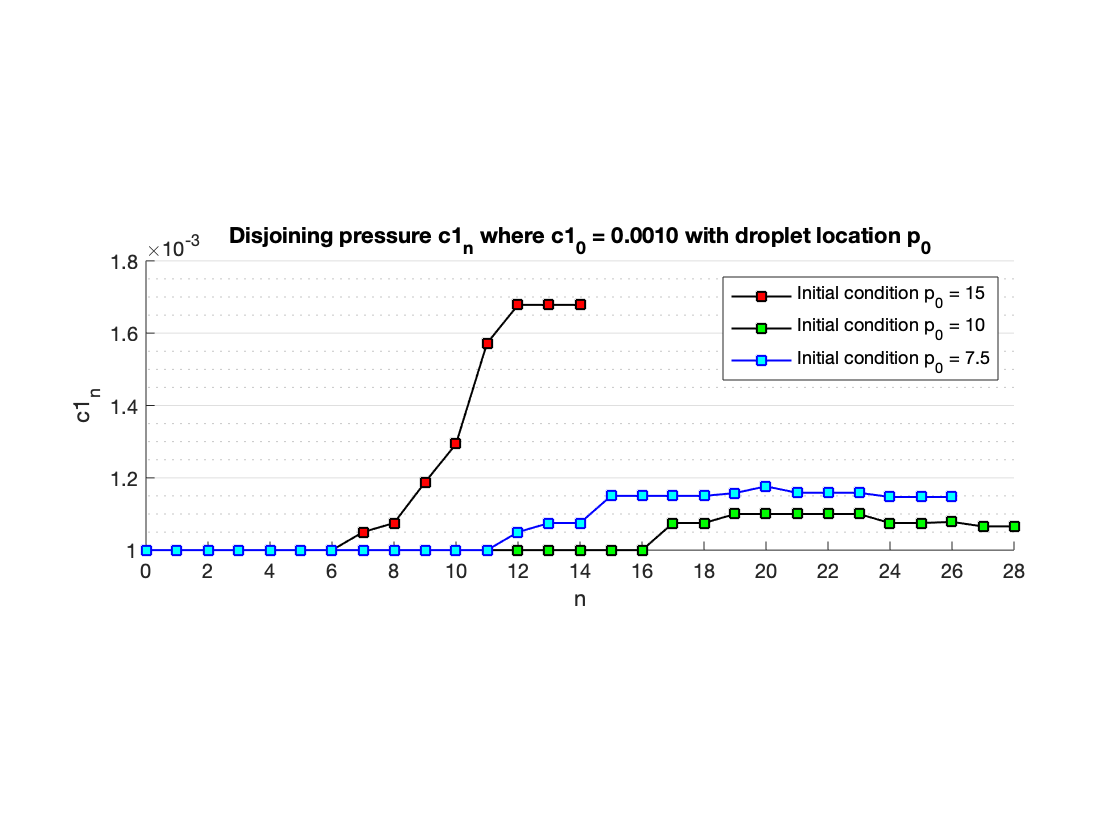


figure;
hold on
plot(0:14,history1_1(:,2),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:28,history1_2(:,2),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:26,history1(:,2),'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c1_n');
xlabel('n');
title('Disjoining pressure c1_n where c1_0 = 0.0010 with droplet location p_0');
legend('Initial condition p_0 = 15','Initial condition p_0 = 10','Initial condition p_0 = 7.5','Location','northeast');
set(gca,'xtick',0:2:100);
xlim([0 28]);
ylim([.001 .0018]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

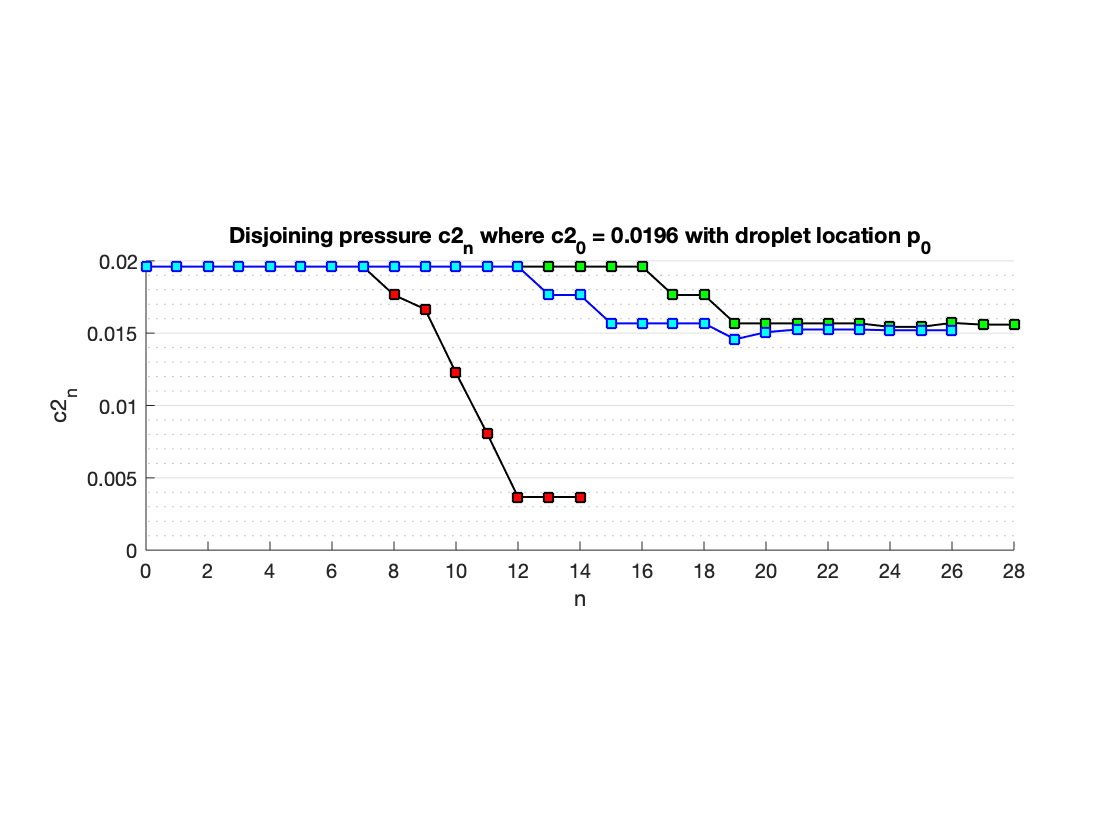



figure;
hold on
plot(0:14,history1_1(:,3),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:28,history1_2(:,3),'k-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:26,history1(:,3),'b-s',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c2_n');
xlabel('n');
title('Disjoining pressure c2_n where c2_0 = 0.0196 with droplet location p_0');
set(gca,'xtick',0:2:100);
xlim([0 28]);
ylim([0 .02]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

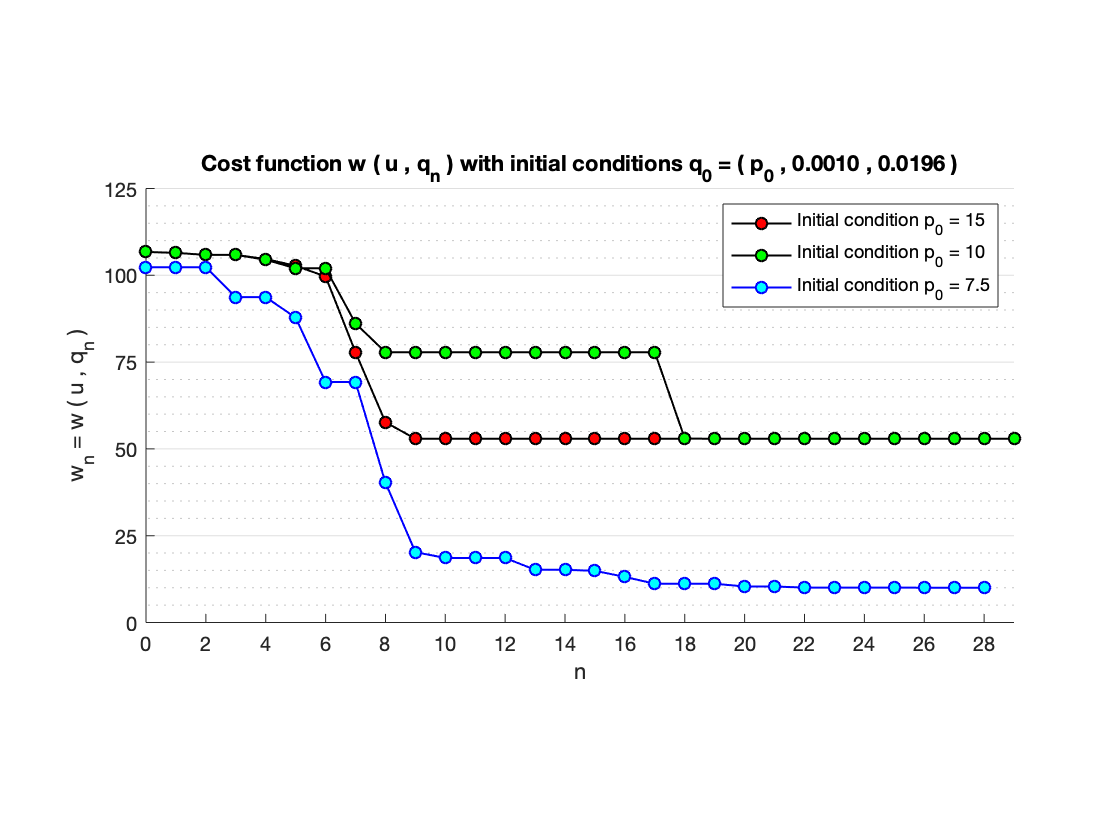

figure;
hold on
plot(0:18,History_1,'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:29,History_2,'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:28,History,'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('w_n = w ( u , q_n )');
xlabel('n');
legend('Initial condition p_0 = 15','Initial condition p_0 = 10','Initial condition p_0 = 7.5','Location','northeast');
title('Cost function w ( u , q_n ) with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 29]);
ylim([0 125]);
set(gca,'xtick',0:2:100);
set(gca,'ytick',0:25:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

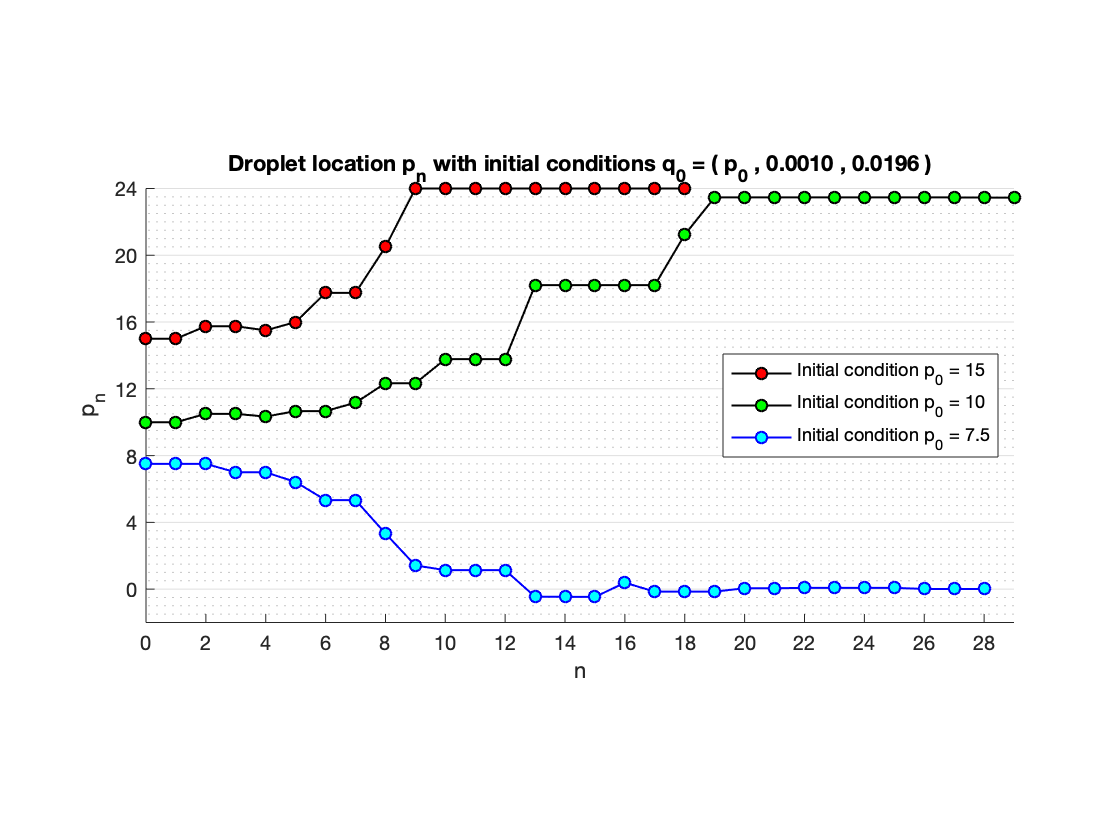


figure;
hold on
plot(0:18,history_1(1,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:29,history_2(1,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:28,history(1,:),'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
ylabel('p_n');
xlabel('n');
legend('Initial condition p_0 = 15','Initial condition p_0 = 10','Initial condition p_0 = 7.5','Location','east');
title('Droplet location p_n with initial conditions q_0 = ( p_0 , 0.0010 , 0.0196 )');
xlim([0 29]);
ylim([-2 24]);
set(gca,'xtick',0:2:100);
set(gca,'ytick',-4:4:500);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
pbaspect([2 1 1]);
box off
hold off

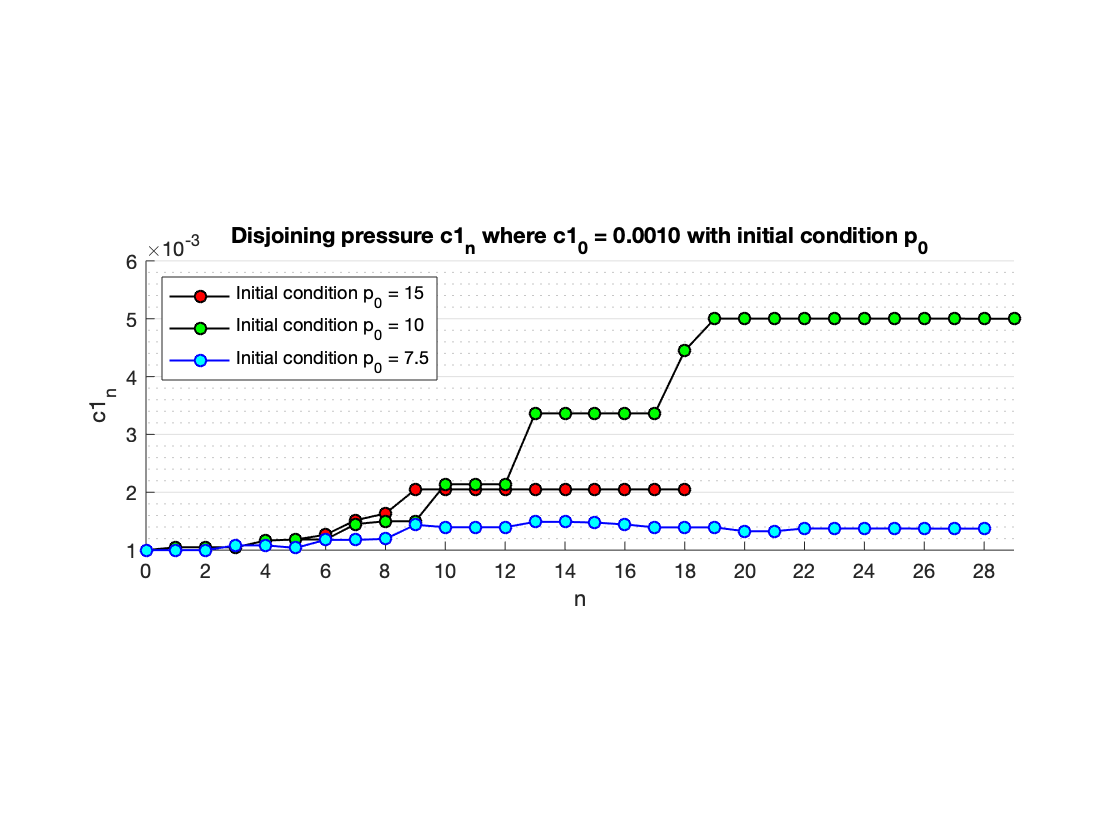


figure;
hold on
plot(0:18,history_1(2,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:29,history_2(2,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:28,history(2,:),'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c1_n');
xlabel('n');
set(gca,'xtick',0:2:100);
title('Disjoining pressure c1_n where c1_0 = 0.0010 with initial condition p_0');
legend('Initial condition p_0 = 15','Initial condition p_0 = 10','Initial condition p_0 = 7.5','Location','northwest');
xlim([0 29]);
ylim([.001 .006]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

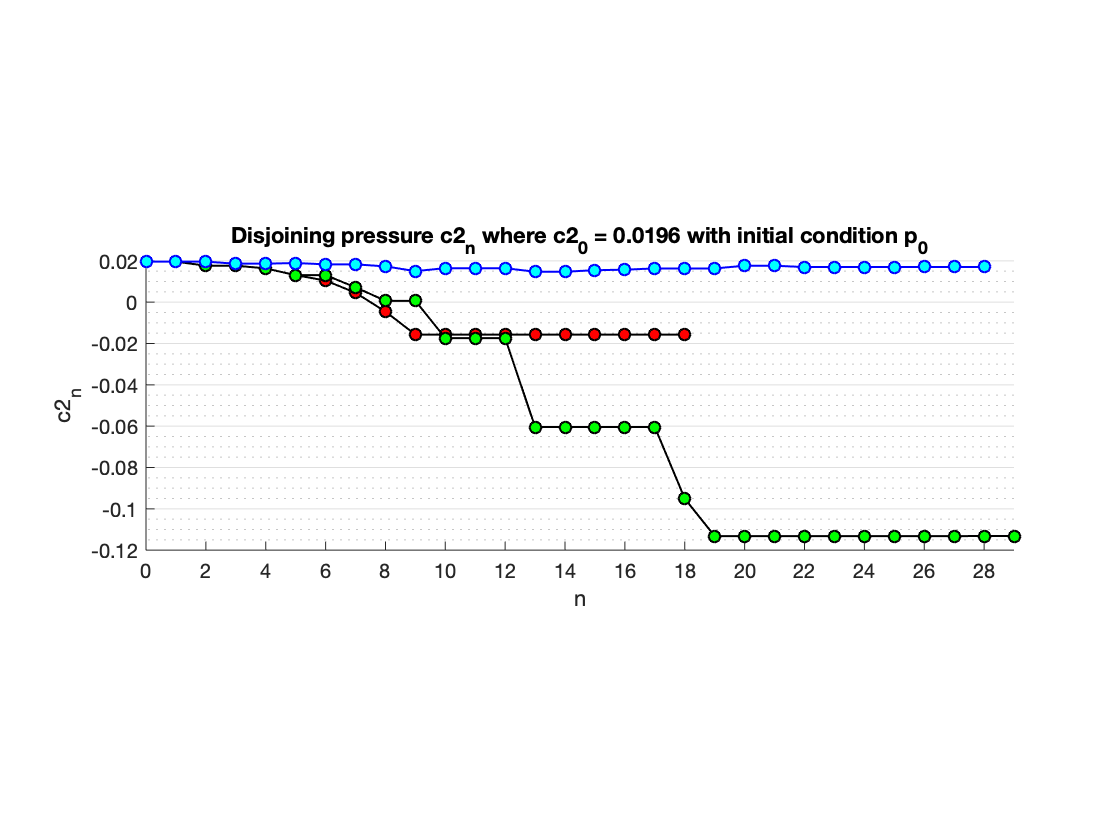


figure;
hold on
plot(0:18,history_1(3,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','r',...
    'LineWidth',1);
plot(0:29,history_2(3,:),'k-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','g',...
    'LineWidth',1);
plot(0:28,history(3,:),'b-o',...
    'MarkerSize',6,...
    'MarkerFaceColor','c',...
    'LineWidth',1);
pbaspect([3 1 1]);
ylabel('c2_n');
xlabel('n');
set(gca,'xtick',0:2:100);
title('Disjoining pressure c2_n where c2_0 = 0.0196 with initial condition p_0');
xlim([0 29]);
ylim([-.12 .02]);
ax = gca;
ax.GridLineStyle = '-';
ax.XGrid = 'off';
ax.YGrid = 'on';
ax.MinorGridLineStyle =':';
ax.XMinorGrid = 'off';
ax.YMinorGrid = 'on';
hold off

var = [A;N;k;y0]; 
% Set time span
tSpan = [1e-6 tfinal]; 
% Creating test matrix to soolve ODE
D1 = full(gallery('tridiag',N,-1,0,1));
D1(N,1)=1;D1(1,N)=-1;
D1 = D1/(2*dx);
D1 = sparse(D1); % D1
D2 = full(gallery('tridiag',N,1,-2,1));
D2(N,1)=1;D2(1,N)=1;
D2 = D2/dx^2;
D2 = sparse(D2);

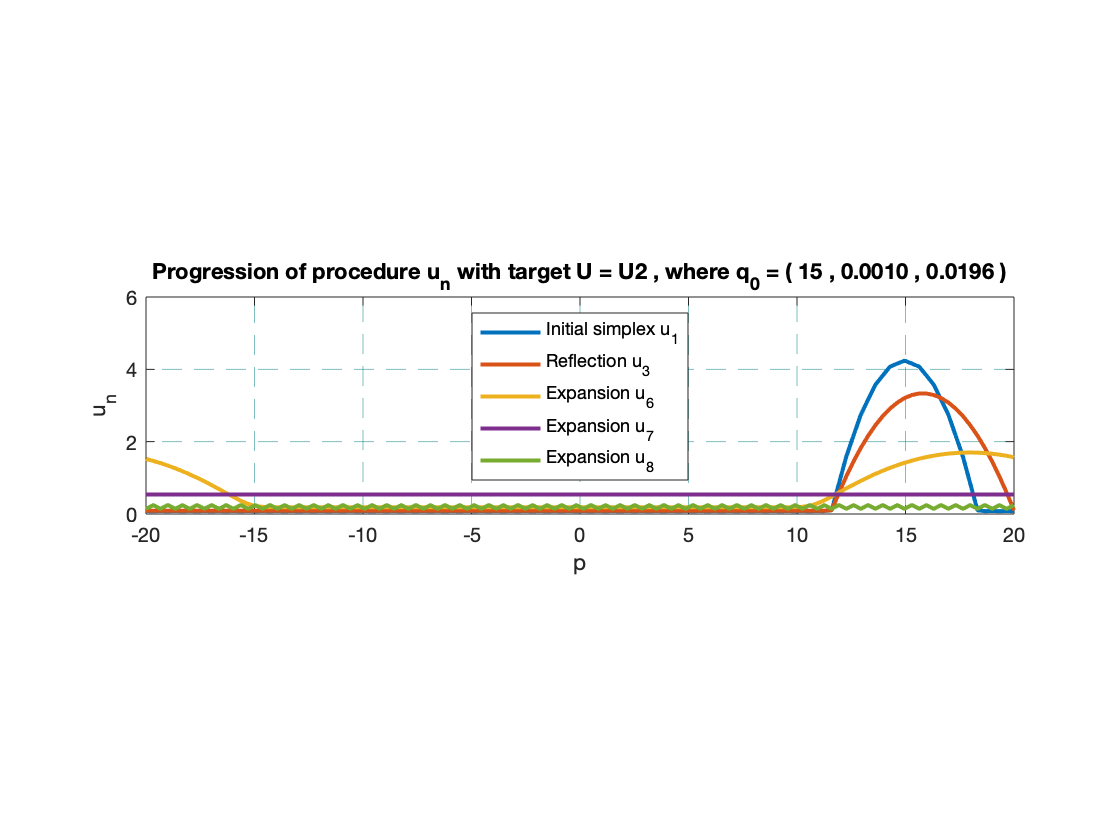


figure;
hold on
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

    hhh1 = hFinalRegion(history_1(:,2),X,var,D1,D2,tSpan);
    ht1 = deval(hhh1,tfinal);
    p1 = plot(X,ht1,'linewidth',2);
    
    hhh1 = hFinalRegion(history_1(:,4),X,var,D1,D2,tSpan);
    ht1 = deval(hhh1,tfinal);
    p1 = plot(X,ht1,'linewidth',2);
    drawnow
    
    drawnow
for i = 6:8
    hhh1 = hFinalRegion(history_1(:,i+1),X,var,D1,D2,tSpan);
    ht1 = deval(hhh1,tfinal);
    p1 = plot(X,ht1,'linewidth',2);
    drawnow
    pause(0.1);
end


legend('Initial simplex u_1',...
    'Reflection u_3',...
    'Expansion u_6',...
    'Expansion u_7',...
    'Expansion u_8',...
    'Location','north');
title('Progression of procedure u_n with target U = U2 , where q_0 = ( 15 , 0.0010 , 0.0196 )');
hold off

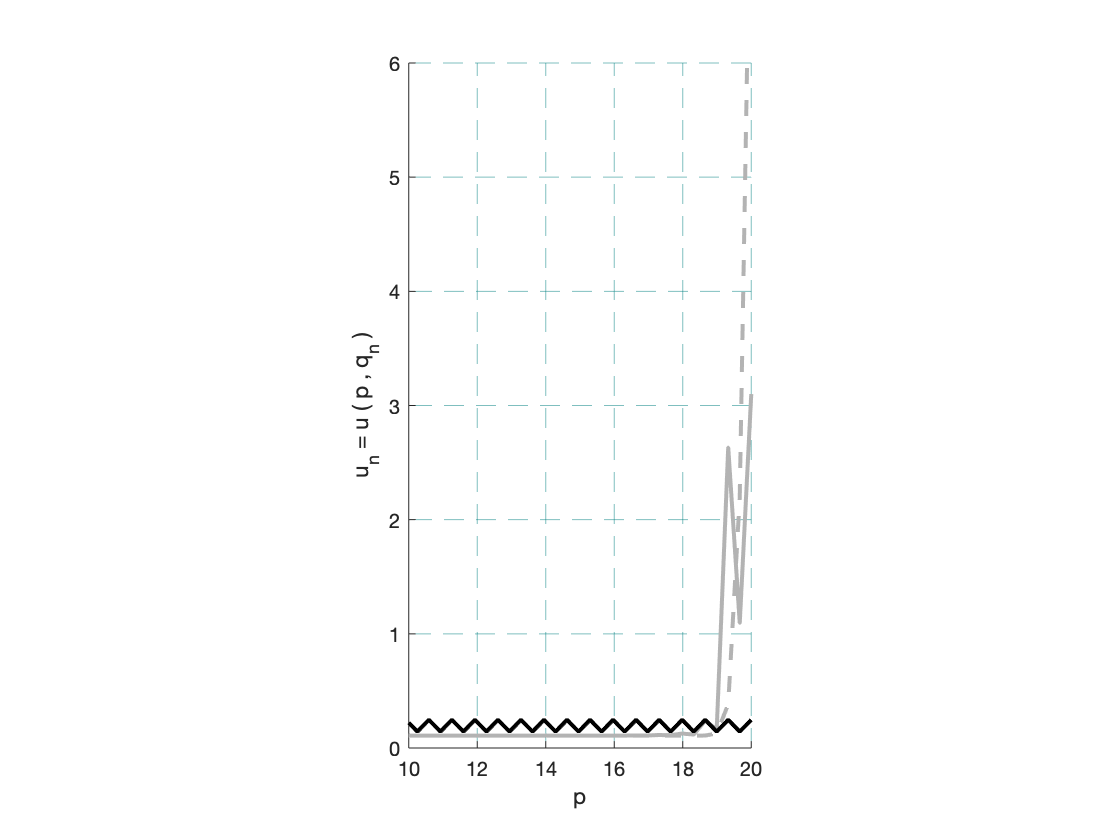


times_1 = logspace(-6,5,3);
hhh_1 = hFinalRegion(history_1(:,9),X,var,D1,D2,times_1);

figure;
hold on
pbaspect([1 2 1]);
xlim([10 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box off
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

    ht1 = deval(hhh_1,times_1(1));
    p_1 = plot(X,ht1,'--','Color',[0.7 0.7 0.7],'linewidth',2);
    drawnow
    pause(0.1);
    
    ht1 = deval(hhh_1,times_1(2));
    p_1 = plot(X,ht1,'-','Color',[0.7 0.7 0.7],'linewidth',2);
    drawnow
    pause(0.1);
    
    ht1 = deval(hhh_1,times_1(3));
    p_1 = plot(X,ht1,'-k','linewidth',2);
    drawnow
    pause(0.1);
    
hold off

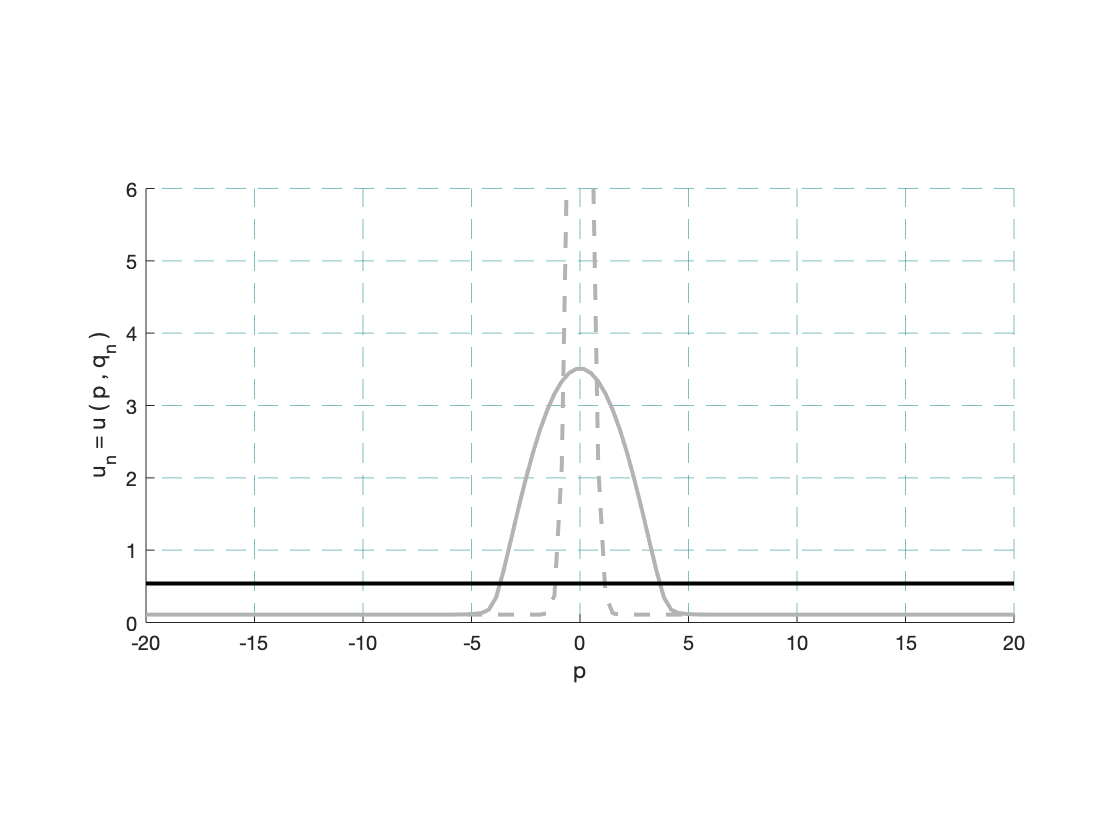




times_1 = logspace(-6,5,3);
hhh_1 = hFinalRegion([0;history_1(2:end,9)],X,var,D1,D2,times_1);

figure;
hold on
pbaspect([2 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box off
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

    ht1 = deval(hhh_1,times_1(1));
    p_1 = plot(X,ht1,'--','Color',[0.7 0.7 0.7],'linewidth',2);
    drawnow
    pause(0.1);
    
    ht1 = deval(hhh_1,times_1(2));
    p_1 = plot(X,ht1,'-','Color',[0.7 0.7 0.7],'linewidth',2);
    drawnow
    pause(0.1);
    
    ht1 = deval(hhh_1,times_1(3));
    p_1 = plot(X,ht1,'-k','linewidth',2);
    drawnow
    pause(0.1);
    
hold off

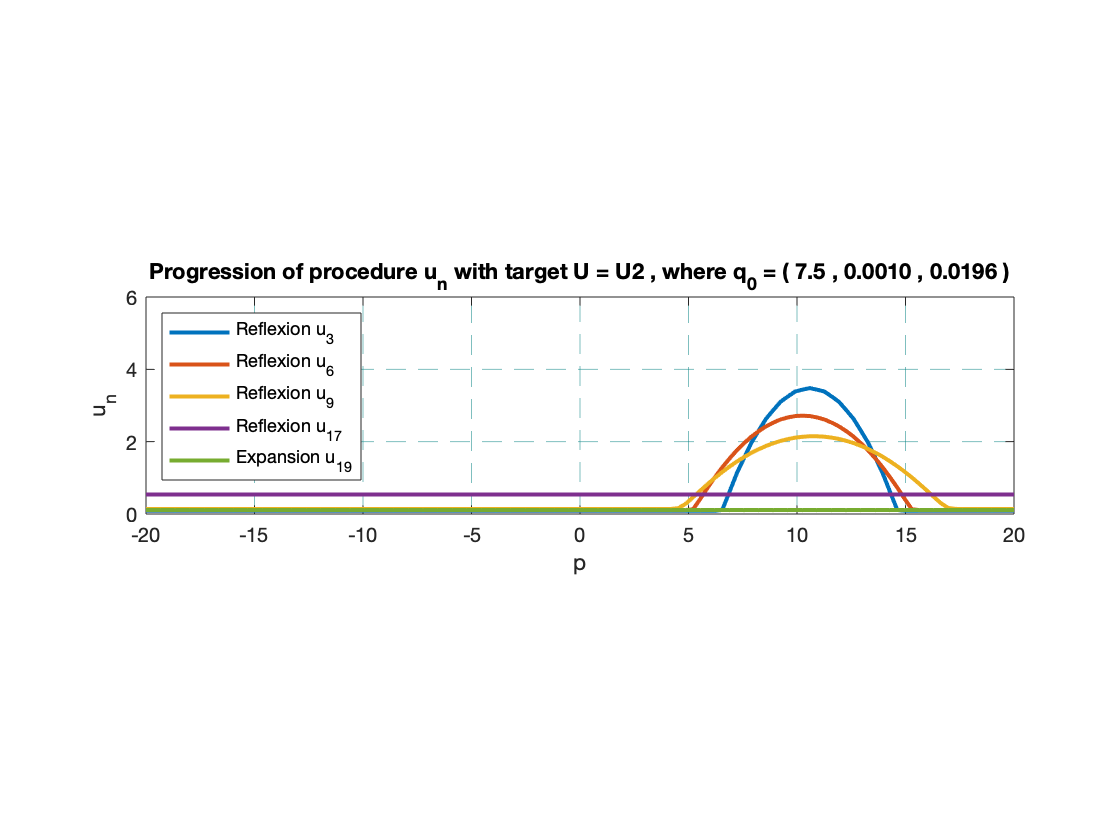

figure;
hold on
pbaspect([4 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

for i = 1:3
    hhh2 = hFinalRegion(history_2(:,2*i+1),X,var,D1,D2,tSpan);
    ht2 = deval(hhh2,tfinal);
    p2 = plot(X,ht2,'linewidth',2);
    drawnow
    pause(0.1);
end

for i = 18:19
    hhh2 = hFinalRegion(history_2(:,i),X,var,D1,D2,tSpan);
    ht2 = deval(hhh2,tfinal);
    p2 = plot(X,ht2,'linewidth',2);
    drawnow
    pause(0.1);
end

legend('Reflexion u_3',...
    'Reflexion u_6',...
    'Reflexion u_9',...
    'Reflexion u_{17}',...
    'Expansion u_{19}',...
    'Location','northwest');
title('Progression of procedure u_n with target U = U2 , where q_0 = ( 7.5 , 0.0010 , 0.0196 )');
hold off

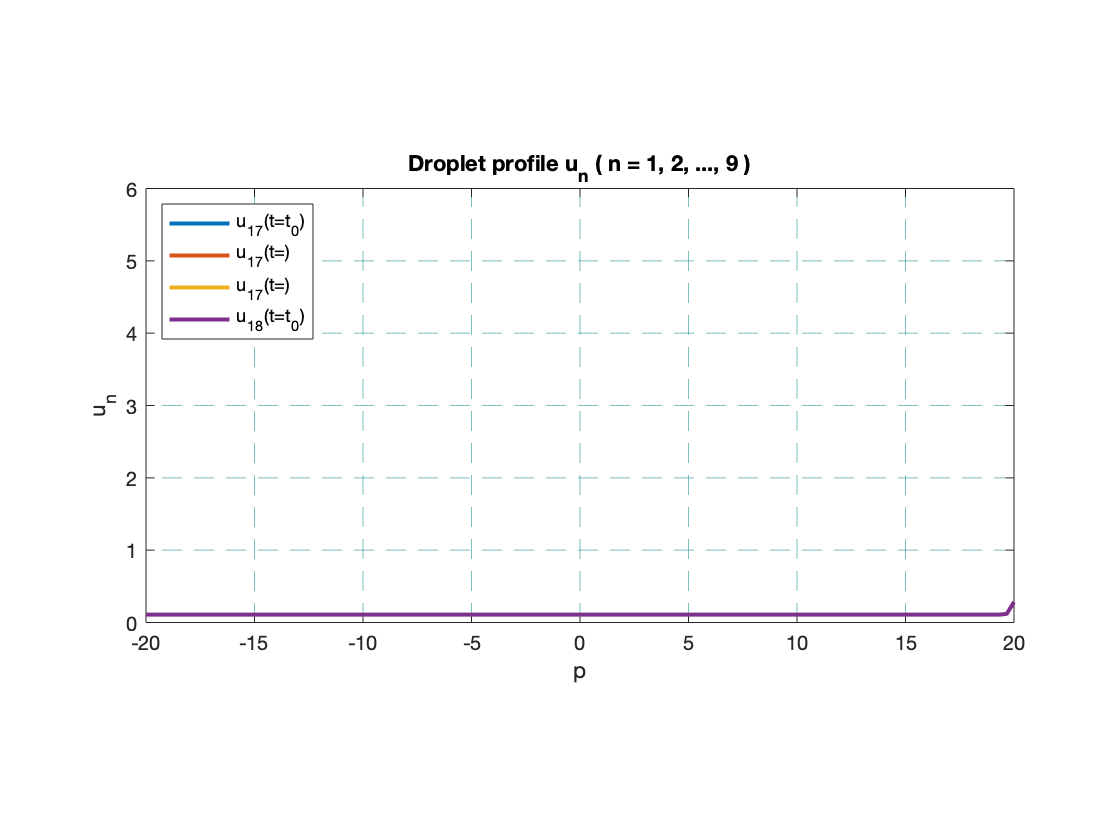


times = logspace(-6,5,81);
hhh_2 = hFinalRegion(history_2(:,19),X,var,D1,D2,tSpan);

figure;
hold on
pbaspect([2 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

for i = 1:4
    ht_2 = deval(hhh_2,t0);
    p_2 = plot(X,ht_2,'linewidth',2);
    drawnow
    pause(0.1);
end

legend('u_{17}(t=t_0)',...
    'u_{17}(t=)',...
    'u_{17}(t=)',...
    'u_{18}(t=t_0)',...
    'Location','northwest');
title('Droplet profile u_n ( n = 1, 2, ..., 9 )');
hold off

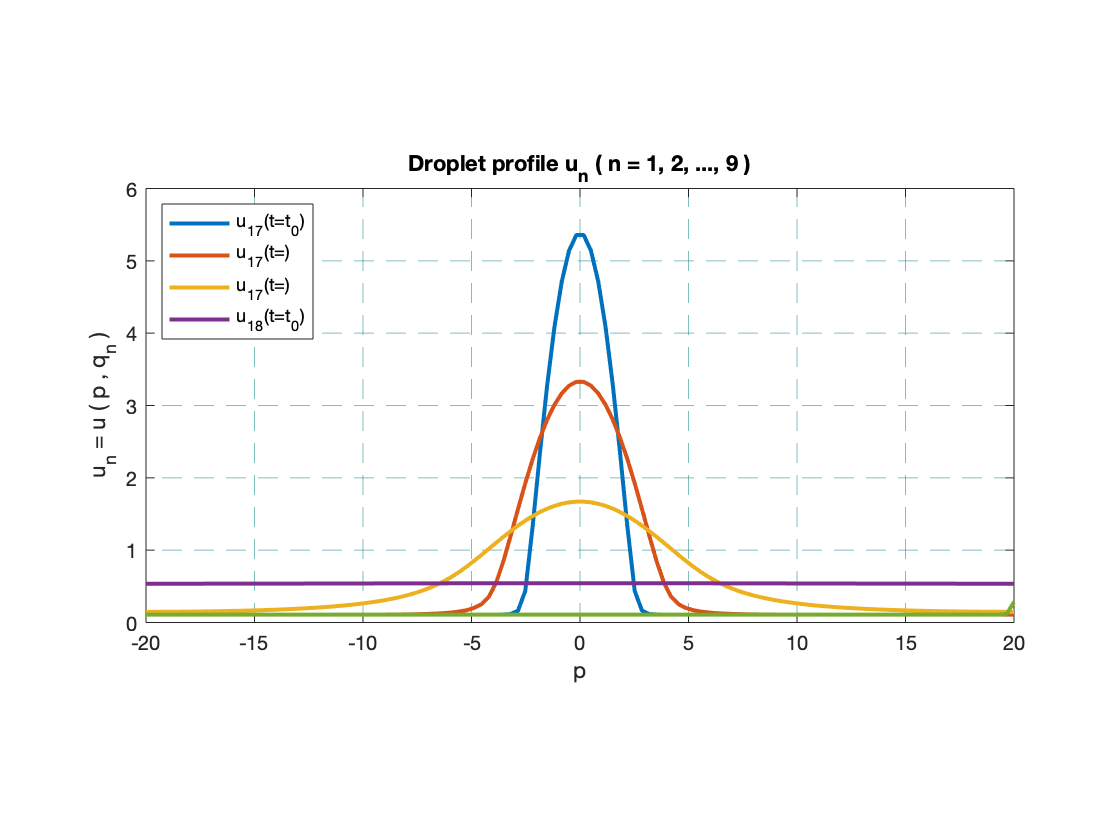



times = logspace(-6,5,81);
hhh_2 = hFinalRegion([0;history_2(2:3,19)],X,var,D1,D2,tSpan);

figure;
hold on
pbaspect([2 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

for i = 3:6
    ht_2 = deval(hhh_2,times(10*i+1));
    p_2 = plot(X,ht_2,'linewidth',2);
    drawnow
    pause(0.1);
end

hhh_2_1 = hFinalRegion(history_2(:,19),X,var,D1,D2,tSpan);
ht_2_1 = deval(hhh_2_1,times(1));
plot(X,ht_2_1,'linewidth',2);
drawnow

legend('u_{17}(t=t_0)',...
    'u_{17}(t=)',...
    'u_{17}(t=)',...
    'u_{18}(t=t_0)',...
    'Location','northwest');
title('Droplet profile u_n ( n = 1, 2, ..., 9 )');
hold off

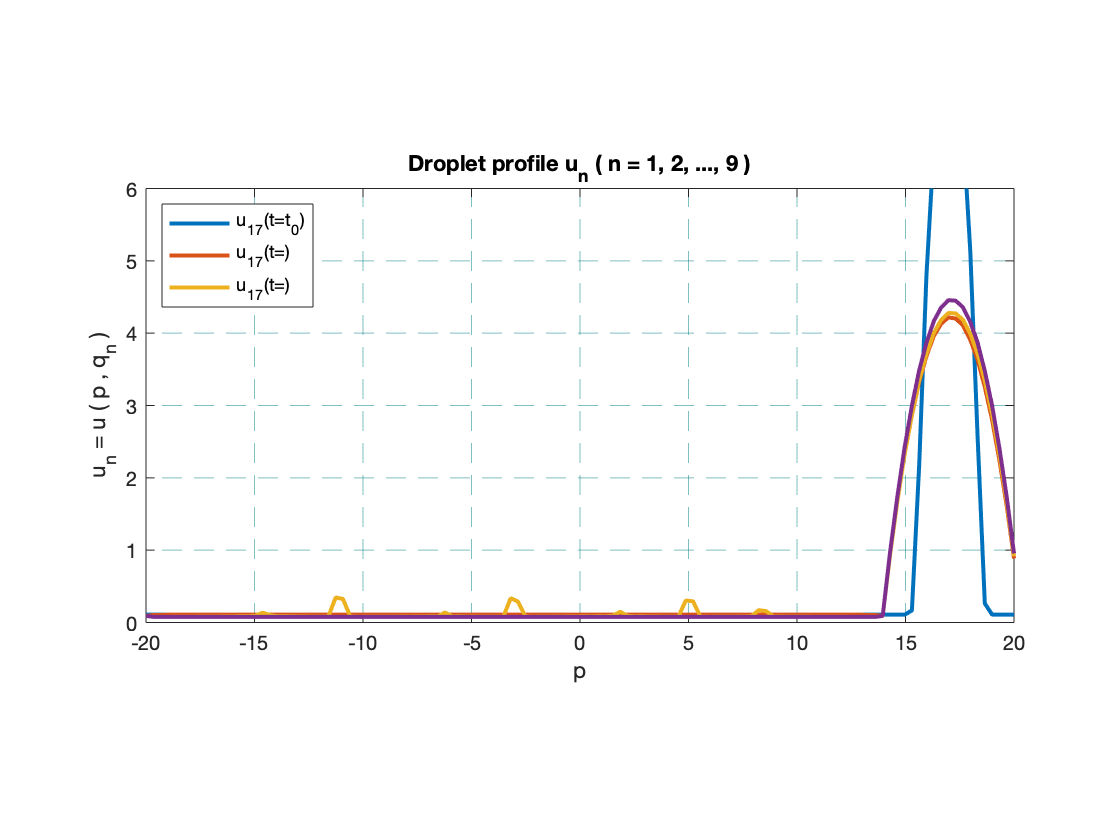


times = logspace(-6,5,5);
hhh_2 = hFinalRegion([17;0.0010;0.0196],X,var,D1,D2,tSpan);

figure;
hold on
pbaspect([2 1 1]);
xlim([-20 20]);
ylim([0 6]);
xlabel('p');
ylabel('u_n = u ( p , q_n )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

for i = 1:4
    ht_2 = deval(hhh_2,times(i+1));
    p_2 = plot(X,ht_2,'linewidth',2);
    drawnow
    pause(0.1);
end

legend('u_{17}(t=t_0)',...
    'u_{17}(t=)',...
    'u_{17}(t=)',...
    'Location','northwest');
title('Droplet profile u_n ( n = 1, 2, ..., 9 )');
hold off

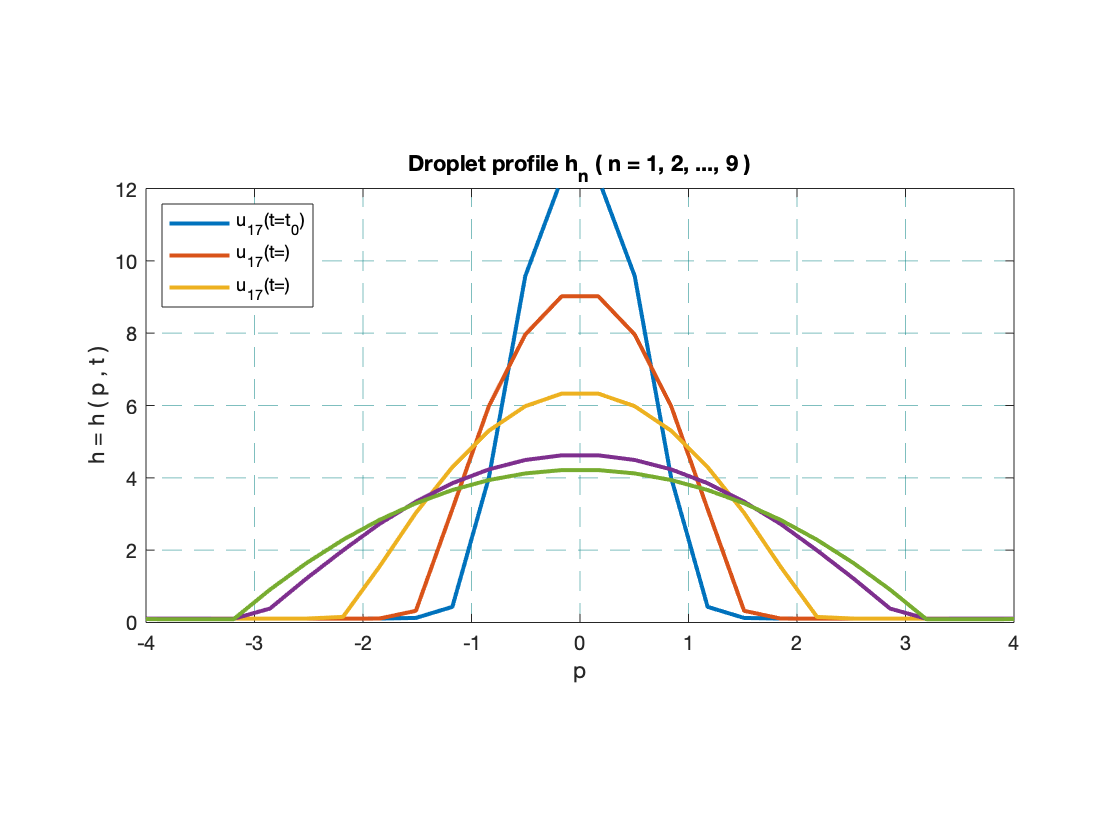


times = logspace(-6,5,10);
hhh_2 = hFinalRegion([0;0.0010;0.0196],X,var,D1,D2,tSpan);

figure;
hold on
pbaspect([2 1 1]);
xlim([-4 4]);
ylim([0 12]);
xlabel('p');
ylabel('h = h ( p , t )');
grid on
box on
ax = gca;
ax.GridColor = [0 .5 .5];
ax.GridLineStyle = '--';
ax.GridAlpha = 0.5;

for i = 2:6
    ht_2 = deval(hhh_2,times(i));
    yt_2 = smooth(ht_2);
    p_2 = plot(X,ht_2,'linewidth',2);
    drawnow
    pause(0.1);
end

legend('u_{17}(t=t_0)',...
    'u_{17}(t=)',...
    'u_{17}(t=)',...
    'Location','northwest');
title('Droplet profile h_n ( n = 1, 2, ..., 9 )');
hold off